images = imageDatastore("data\", "IncludeSubfolders", true, "LabelSource", "foldernames");
countEachLabel(images)

ans = 2×2 table
    Label     Count
    ______    _____

    neg_64    2436 
    pos       2416 


img_classes = {'pos', 'neg_64'};

train_count = 2300;
test_count = 100;

[images_train, images_test] = splitEachLabel(images, train_count, test_count, 'Include', img_classes);



% Przygotowanie danych treningowych
X_train = zeros(length(images_train.Files), 3780);
Y_train = images_train.Labels;

for i=1:length(images_train.Files)
    if mod(i, 500) == 0
        fprintf("Extracting HOG features i=%d...\n", i);
    end
    I = imread(images_train.Files{i});
    try
        [hog, vis] = extractHOGFeatures(I);
        X_train(i,:) = hog;
    catch ME
        fprintf("Error processing file %s", images_train.Files{i});
        fprintf("Error: %s", ME);
    end
end

Extracting HOG features i=500...
Extracting HOG features i=1000...
Extracting HOG features i=1500...
Extracting HOG features i=2000...
Extracting HOG features i=2500...
Extracting HOG features i=3000...
Extracting HOG features i=3500...
Extracting HOG features i=4000...
Extracting HOG features i=4500...




% Przygotowanie danych testowych
X_test = zeros(length(images_test.Files), 3780);
Y_test = images_test.Labels;

for i=1:length(images_test.Files)
    if mod(i, 500) == 0
        fprintf("Extracting HOG features i=%d...\n", i);
    end
    I = imread(images_test.Files{i});
    try
        [hog, vis] = extractHOGFeatures(I);
        % imshow(I, 'InitialMagnification', 500);
        % hold on;
        % plot(vis);
        X_test(i,:) = hog;
    catch ME
        fprintf("Error processing file %s", images_test.Files{i});
        fprintf("Error: %s", ME);
    end
end


model = fitcknn(X_train,Y_train,'NumNeighbors',10,'Standardize',1);


clear loss;
loss_s = loss(model, X_test, Y_test, 'Lossfun', 'classiferror');
fprintf("loss=%f\n", loss_s);

loss=0.315000


ans = categorical
     neg_64 


figure;
It = imread("people_1.jpg");
imshow(It);
hold on
[hogt,vist] = extractHOGFeatures(It);
plot(vist)

scale = 1

count_x = 25

count_y = 11

level=1 count_x=25 count_y=11

level=1 0/275 (j=0, i=0)... 


pred=neg_64


level=1 1/275 (j=0, i=1)... 


pred=neg_64


level=1 2/275 (j=0, i=2)... 


pred=neg_64


level=1 3/275 (j=0, i=3)... 


pred=neg_64


level=1 4/275 (j=0, i=4)... 


pred=neg_64


level=1 5/275 (j=0, i=5)... 


pred=neg_64


level=1 6/275 (j=0, i=6)... 


pred=neg_64


level=1 7/275 (j=0, i=7)... 


pred=neg_64


level=1 8/275 (j=0, i=8)... 


pred=neg_64


level=1 9/275 (j=0, i=9)... 


pred=neg_64


level=1 10/275 (j=0, i=10)... 


pred=neg_64


level=1 11/275 (j=0, i=11)... 


pred=neg_64


level=1 12/275 (j=0, i=12)... 


pred=neg_64


level=1 13/275 (j=0, i=13)... 


pred=neg_64


level=1 14/275 (j=0, i=14)... 


pred=neg_64


level=1 15/275 (j=0, i=15)... 


pred=neg_64


level=1 16/275 (j=0, i=16)... 


pred=neg_64


level=1 17/275 (j=0, i=17)... 


pred=neg_64


level=1 18/275 (j=0, i=18)... 


pred=neg_64


level=1 19/275 (j=0, i=19)... 


pred=neg_64


level=1 20/275 (j=0, i=20)... 


pred=neg_64


level=1 21/275 (j=0, i=21)... 


pred=neg_64


level=1 22/275 (j=0, i=22)... 


pred=neg_64


level=1 23/275 (j=0, i=23)... 


pred=neg_64


level=1 24/275 (j=0, i=24)... 


pred=neg_64


level=1 25/275 (j=1, i=0)... 


pred=neg_64


level=1 26/275 (j=1, i=1)... 


pred=neg_64


level=1 27/275 (j=1, i=2)... 


pred=neg_64


level=1 28/275 (j=1, i=3)... 


pred=neg_64


level=1 29/275 (j=1, i=4)... 


pred=neg_64


level=1 30/275 (j=1, i=5)... 


pred=neg_64


level=1 31/275 (j=1, i=6)... 


pred=neg_64


level=1 32/275 (j=1, i=7)... 


pred=neg_64


level=1 33/275 (j=1, i=8)... 


pred=neg_64


level=1 34/275 (j=1, i=9)... 


pred=neg_64


level=1 35/275 (j=1, i=10)... 


pred=neg_64


level=1 36/275 (j=1, i=11)... 


pred=neg_64


level=1 37/275 (j=1, i=12)... 


pred=neg_64


level=1 38/275 (j=1, i=13)... 


pred=neg_64


level=1 39/275 (j=1, i=14)... 


pred=neg_64


level=1 40/275 (j=1, i=15)... 


pred=neg_64


level=1 41/275 (j=1, i=16)... 


pred=neg_64


level=1 42/275 (j=1, i=17)... 


pred=neg_64


level=1 43/275 (j=1, i=18)... 


pred=neg_64


level=1 44/275 (j=1, i=19)... 


pred=neg_64


level=1 45/275 (j=1, i=20)... 


pred=neg_64


level=1 46/275 (j=1, i=21)... 


pred=neg_64


level=1 47/275 (j=1, i=22)... 


pred=neg_64


level=1 48/275 (j=1, i=23)... 


pred=neg_64


level=1 49/275 (j=1, i=24)... 


pred=neg_64


level=1 50/275 (j=2, i=0)... 


pred=neg_64


level=1 51/275 (j=2, i=1)... 


pred=neg_64


level=1 52/275 (j=2, i=2)... 


pred=neg_64


level=1 53/275 (j=2, i=3)... 


pred=neg_64


level=1 54/275 (j=2, i=4)... 


pred=neg_64


level=1 55/275 (j=2, i=5)... 


pred=neg_64


level=1 56/275 (j=2, i=6)... 


pred=neg_64


level=1 57/275 (j=2, i=7)... 


pred=neg_64


level=1 58/275 (j=2, i=8)... 


pred=neg_64


level=1 59/275 (j=2, i=9)... 


pred=neg_64


level=1 60/275 (j=2, i=10)... 


pred=neg_64


level=1 61/275 (j=2, i=11)... 


pred=neg_64


level=1 62/275 (j=2, i=12)... 


pred=neg_64


level=1 63/275 (j=2, i=13)... 


pred=neg_64


level=1 64/275 (j=2, i=14)... 


pred=neg_64


level=1 65/275 (j=2, i=15)... 


pred=neg_64


level=1 66/275 (j=2, i=16)... 


pred=neg_64


level=1 67/275 (j=2, i=17)... 


pred=neg_64


level=1 68/275 (j=2, i=18)... 


pred=neg_64


level=1 69/275 (j=2, i=19)... 


pred=neg_64


level=1 70/275 (j=2, i=20)... 


pred=neg_64


level=1 71/275 (j=2, i=21)... 


pred=neg_64


level=1 72/275 (j=2, i=22)... 


pred=neg_64


level=1 73/275 (j=2, i=23)... 


pred=neg_64


level=1 74/275 (j=2, i=24)... 


pred=neg_64


level=1 75/275 (j=3, i=0)... 


pred=neg_64


level=1 76/275 (j=3, i=1)... 


pred=neg_64


level=1 77/275 (j=3, i=2)... 


pred=neg_64


level=1 78/275 (j=3, i=3)... 


pred=neg_64


level=1 79/275 (j=3, i=4)... 


pred=neg_64


level=1 80/275 (j=3, i=5)... 


pred=neg_64


level=1 81/275 (j=3, i=6)... 


pred=neg_64


level=1 82/275 (j=3, i=7)... 


pred=neg_64


level=1 83/275 (j=3, i=8)... 


pred=neg_64


level=1 84/275 (j=3, i=9)... 


pred=neg_64


level=1 85/275 (j=3, i=10)... 


pred=neg_64


level=1 86/275 (j=3, i=11)... 


pred=neg_64


level=1 87/275 (j=3, i=12)... 


pred=neg_64


level=1 88/275 (j=3, i=13)... 


pred=neg_64


level=1 89/275 (j=3, i=14)... 


pred=neg_64


level=1 90/275 (j=3, i=15)... 


pred=neg_64


level=1 91/275 (j=3, i=16)... 


pred=neg_64


level=1 92/275 (j=3, i=17)... 


pred=neg_64


level=1 93/275 (j=3, i=18)... 


pred=neg_64


level=1 94/275 (j=3, i=19)... 


pred=neg_64


level=1 95/275 (j=3, i=20)... 


pred=neg_64


level=1 96/275 (j=3, i=21)... 


pred=neg_64


level=1 97/275 (j=3, i=22)... 


pred=neg_64


level=1 98/275 (j=3, i=23)... 


pred=neg_64


level=1 99/275 (j=3, i=24)... 


pred=neg_64


level=1 100/275 (j=4, i=0)... 


pred=neg_64


level=1 101/275 (j=4, i=1)... 


pred=neg_64


level=1 102/275 (j=4, i=2)... 


pred=neg_64


level=1 103/275 (j=4, i=3)... 


pred=neg_64


level=1 104/275 (j=4, i=4)... 


pred=neg_64


level=1 105/275 (j=4, i=5)... 


pred=neg_64


level=1 106/275 (j=4, i=6)... 


pred=neg_64


level=1 107/275 (j=4, i=7)... 


pred=neg_64


level=1 108/275 (j=4, i=8)... 


pred=neg_64


level=1 109/275 (j=4, i=9)... 


pred=neg_64


level=1 110/275 (j=4, i=10)... 


pred=neg_64


level=1 111/275 (j=4, i=11)... 


pred=neg_64


level=1 112/275 (j=4, i=12)... 


pred=neg_64


level=1 113/275 (j=4, i=13)... 


pred=neg_64


level=1 114/275 (j=4, i=14)... 


pred=neg_64


level=1 115/275 (j=4, i=15)... 


pred=neg_64


level=1 116/275 (j=4, i=16)... 


pred=neg_64


level=1 117/275 (j=4, i=17)... 


pred=neg_64


level=1 118/275 (j=4, i=18)... 


pred=neg_64


level=1 119/275 (j=4, i=19)... 


pred=neg_64


level=1 120/275 (j=4, i=20)... 


pred=neg_64


level=1 121/275 (j=4, i=21)... 


pred=neg_64


level=1 122/275 (j=4, i=22)... 


pred=neg_64


level=1 123/275 (j=4, i=23)... 


pred=neg_64


level=1 124/275 (j=4, i=24)... 


pred=neg_64


level=1 125/275 (j=5, i=0)... 


pred=neg_64


level=1 126/275 (j=5, i=1)... 


pred=neg_64


level=1 127/275 (j=5, i=2)... 


pred=neg_64


level=1 128/275 (j=5, i=3)... 


pred=neg_64


level=1 129/275 (j=5, i=4)... 


pred=neg_64


level=1 130/275 (j=5, i=5)... 


pred=neg_64


level=1 131/275 (j=5, i=6)... 


pred=neg_64


level=1 132/275 (j=5, i=7)... 


pred=neg_64


level=1 133/275 (j=5, i=8)... 


pred=neg_64


level=1 134/275 (j=5, i=9)... 


pred=neg_64


level=1 135/275 (j=5, i=10)... 


pred=neg_64


level=1 136/275 (j=5, i=11)... 


pred=neg_64


level=1 137/275 (j=5, i=12)... 


pred=neg_64


level=1 138/275 (j=5, i=13)... 


pred=neg_64


level=1 139/275 (j=5, i=14)... 


pred=neg_64


level=1 140/275 (j=5, i=15)... 


pred=neg_64


level=1 141/275 (j=5, i=16)... 


pred=neg_64


level=1 142/275 (j=5, i=17)... 


pred=neg_64


level=1 143/275 (j=5, i=18)... 


pred=neg_64


level=1 144/275 (j=5, i=19)... 


pred=neg_64


level=1 145/275 (j=5, i=20)... 


pred=neg_64


level=1 146/275 (j=5, i=21)... 


pred=neg_64


level=1 147/275 (j=5, i=22)... 


pred=neg_64


level=1 148/275 (j=5, i=23)... 


pred=neg_64


level=1 149/275 (j=5, i=24)... 


pred=neg_64


level=1 150/275 (j=6, i=0)... 


pred=neg_64


level=1 151/275 (j=6, i=1)... 


pred=neg_64


level=1 152/275 (j=6, i=2)... 


pred=neg_64


level=1 153/275 (j=6, i=3)... 


pred=neg_64


level=1 154/275 (j=6, i=4)... 


pred=neg_64


level=1 155/275 (j=6, i=5)... 


pred=neg_64


level=1 156/275 (j=6, i=6)... 


pred=neg_64


level=1 157/275 (j=6, i=7)... 


pred=neg_64


level=1 158/275 (j=6, i=8)... 


pred=neg_64


level=1 159/275 (j=6, i=9)... 


pred=neg_64


level=1 160/275 (j=6, i=10)... 


pred=neg_64


level=1 161/275 (j=6, i=11)... 


pred=neg_64


level=1 162/275 (j=6, i=12)... 


pred=neg_64


level=1 163/275 (j=6, i=13)... 


pred=neg_64


level=1 164/275 (j=6, i=14)... 


pred=neg_64


level=1 165/275 (j=6, i=15)... 


pred=neg_64


level=1 166/275 (j=6, i=16)... 


pred=neg_64


level=1 167/275 (j=6, i=17)... 


pred=neg_64


level=1 168/275 (j=6, i=18)... 


pred=neg_64


level=1 169/275 (j=6, i=19)... 


pred=neg_64


level=1 170/275 (j=6, i=20)... 


pred=neg_64


level=1 171/275 (j=6, i=21)... 


pred=neg_64


level=1 172/275 (j=6, i=22)... 


pred=neg_64


level=1 173/275 (j=6, i=23)... 


pred=neg_64


level=1 174/275 (j=6, i=24)... 


pred=neg_64


level=1 175/275 (j=7, i=0)... 


pred=neg_64


level=1 176/275 (j=7, i=1)... 


pred=neg_64


level=1 177/275 (j=7, i=2)... 


pred=neg_64


level=1 178/275 (j=7, i=3)... 


pred=neg_64


level=1 179/275 (j=7, i=4)... 


pred=neg_64


level=1 180/275 (j=7, i=5)... 


pred=neg_64


level=1 181/275 (j=7, i=6)... 


pred=neg_64


level=1 182/275 (j=7, i=7)... 


pred=neg_64


level=1 183/275 (j=7, i=8)... 


pred=neg_64


level=1 184/275 (j=7, i=9)... 


pred=neg_64


level=1 185/275 (j=7, i=10)... 


pred=neg_64


level=1 186/275 (j=7, i=11)... 


pred=neg_64


level=1 187/275 (j=7, i=12)... 


pred=neg_64


level=1 188/275 (j=7, i=13)... 


pred=neg_64


level=1 189/275 (j=7, i=14)... 


pred=neg_64


level=1 190/275 (j=7, i=15)... 


pred=neg_64


level=1 191/275 (j=7, i=16)... 


pred=neg_64


level=1 192/275 (j=7, i=17)... 


pred=neg_64


level=1 193/275 (j=7, i=18)... 


pred=neg_64


level=1 194/275 (j=7, i=19)... 


pred=neg_64


level=1 195/275 (j=7, i=20)... 


pred=neg_64


level=1 196/275 (j=7, i=21)... 


pred=neg_64


level=1 197/275 (j=7, i=22)... 


pred=neg_64


level=1 198/275 (j=7, i=23)... 


pred=neg_64


level=1 199/275 (j=7, i=24)... 


pred=neg_64


level=1 200/275 (j=8, i=0)... 


pred=neg_64


level=1 201/275 (j=8, i=1)... 


pred=neg_64


level=1 202/275 (j=8, i=2)... 


pred=neg_64


level=1 203/275 (j=8, i=3)... 


pred=neg_64


level=1 204/275 (j=8, i=4)... 


pred=neg_64


level=1 205/275 (j=8, i=5)... 


pred=neg_64


level=1 206/275 (j=8, i=6)... 


pred=neg_64


level=1 207/275 (j=8, i=7)... 


pred=neg_64


level=1 208/275 (j=8, i=8)... 


pred=neg_64


level=1 209/275 (j=8, i=9)... 


pred=neg_64


level=1 210/275 (j=8, i=10)... 


pred=neg_64


level=1 211/275 (j=8, i=11)... 


pred=neg_64


level=1 212/275 (j=8, i=12)... 


pred=neg_64


level=1 213/275 (j=8, i=13)... 


pred=neg_64


level=1 214/275 (j=8, i=14)... 


pred=neg_64


level=1 215/275 (j=8, i=15)... 


pred=neg_64


level=1 216/275 (j=8, i=16)... 


pred=neg_64


level=1 217/275 (j=8, i=17)... 


pred=neg_64


level=1 218/275 (j=8, i=18)... 


pred=neg_64


level=1 219/275 (j=8, i=19)... 


pred=neg_64


level=1 220/275 (j=8, i=20)... 


pred=neg_64


level=1 221/275 (j=8, i=21)... 


pred=neg_64


level=1 222/275 (j=8, i=22)... 


pred=neg_64


level=1 223/275 (j=8, i=23)... 


pred=neg_64


level=1 224/275 (j=8, i=24)... 


pred=neg_64


level=1 225/275 (j=9, i=0)... 


pred=neg_64


level=1 226/275 (j=9, i=1)... 


pred=neg_64


level=1 227/275 (j=9, i=2)... 


pred=neg_64


level=1 228/275 (j=9, i=3)... 


pred=neg_64


level=1 229/275 (j=9, i=4)... 


pred=neg_64


level=1 230/275 (j=9, i=5)... 


pred=neg_64


level=1 231/275 (j=9, i=6)... 


pred=neg_64


level=1 232/275 (j=9, i=7)... 


pred=neg_64


level=1 233/275 (j=9, i=8)... 


pred=neg_64


level=1 234/275 (j=9, i=9)... 


pred=neg_64


level=1 235/275 (j=9, i=10)... 


pred=neg_64


level=1 236/275 (j=9, i=11)... 


pred=neg_64


level=1 237/275 (j=9, i=12)... 


pred=neg_64


level=1 238/275 (j=9, i=13)... 


pred=neg_64


level=1 239/275 (j=9, i=14)... 


pred=neg_64


level=1 240/275 (j=9, i=15)... 


pred=neg_64


level=1 241/275 (j=9, i=16)... 


pred=neg_64


level=1 242/275 (j=9, i=17)... 


pred=neg_64


level=1 243/275 (j=9, i=18)... 


pred=neg_64


level=1 244/275 (j=9, i=19)... 


pred=neg_64


level=1 245/275 (j=9, i=20)... 


pred=neg_64


level=1 246/275 (j=9, i=21)... 


pred=neg_64


level=1 247/275 (j=9, i=22)... 


pred=neg_64


level=1 248/275 (j=9, i=23)... 


pred=neg_64


level=1 249/275 (j=9, i=24)... 


pred=neg_64


level=1 250/275 (j=10, i=0)... 


pred=neg_64


level=1 251/275 (j=10, i=1)... 


pred=neg_64


level=1 252/275 (j=10, i=2)... 


pred=neg_64


level=1 253/275 (j=10, i=3)... 


pred=neg_64


level=1 254/275 (j=10, i=4)... 


pred=neg_64


level=1 255/275 (j=10, i=5)... 


pred=neg_64


level=1 256/275 (j=10, i=6)... 


pred=neg_64


level=1 257/275 (j=10, i=7)... 


pred=neg_64


level=1 258/275 (j=10, i=8)... 


pred=neg_64


level=1 259/275 (j=10, i=9)... 


pred=neg_64


level=1 260/275 (j=10, i=10)... 


pred=neg_64


level=1 261/275 (j=10, i=11)... 


pred=neg_64


level=1 262/275 (j=10, i=12)... 


pred=neg_64


level=1 263/275 (j=10, i=13)... 


pred=neg_64


level=1 264/275 (j=10, i=14)... 


pred=neg_64


level=1 265/275 (j=10, i=15)... 


pred=neg_64


level=1 266/275 (j=10, i=16)... 


pred=neg_64


level=1 267/275 (j=10, i=17)... 


pred=neg_64


level=1 268/275 (j=10, i=18)... 


pred=neg_64


level=1 269/275 (j=10, i=19)... 


pred=neg_64


level=1 270/275 (j=10, i=20)... 


pred=neg_64


level=1 271/275 (j=10, i=21)... 


pred=neg_64


level=1 272/275 (j=10, i=22)... 


pred=neg_64


level=1 273/275 (j=10, i=23)... 


pred=neg_64


level=1 274/275 (j=10, i=24)... 


pred=neg_64


best_score = 0

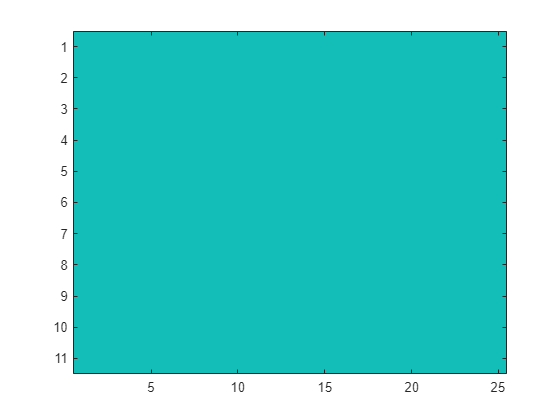

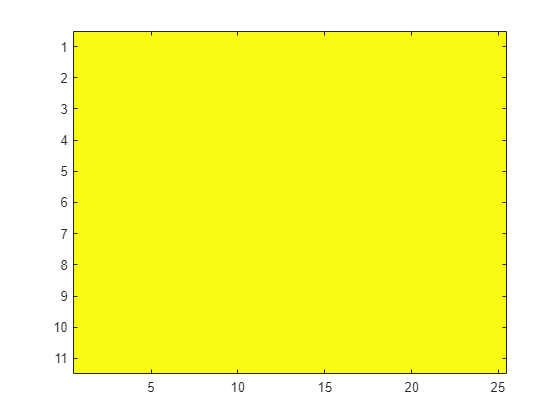

scale = 0.8000

count_x = 20

count_y = 8

level=2 count_x=20 count_y=8

level=2 0/160 (j=0, i=0)... 


pred=neg_64


level=2 1/160 (j=0, i=1)... 


pred=neg_64


level=2 2/160 (j=0, i=2)... 


pred=neg_64


level=2 3/160 (j=0, i=3)... 


pred=neg_64


level=2 4/160 (j=0, i=4)... 


pred=neg_64


level=2 5/160 (j=0, i=5)... 


pred=neg_64


level=2 6/160 (j=0, i=6)... 


pred=neg_64


level=2 7/160 (j=0, i=7)... 


pred=neg_64


level=2 8/160 (j=0, i=8)... 


pred=neg_64


level=2 9/160 (j=0, i=9)... 


pred=neg_64


level=2 10/160 (j=0, i=10)... 


pred=neg_64


level=2 11/160 (j=0, i=11)... 


pred=neg_64


level=2 12/160 (j=0, i=12)... 


pred=neg_64


level=2 13/160 (j=0, i=13)... 


pred=neg_64


level=2 14/160 (j=0, i=14)... 


pred=neg_64


level=2 15/160 (j=0, i=15)... 


pred=neg_64


level=2 16/160 (j=0, i=16)... 


pred=neg_64


level=2 17/160 (j=0, i=17)... 


pred=neg_64


level=2 18/160 (j=0, i=18)... 


pred=neg_64


level=2 19/160 (j=0, i=19)... 


pred=neg_64


level=2 20/160 (j=1, i=0)... 


pred=neg_64


level=2 21/160 (j=1, i=1)... 


pred=neg_64


level=2 22/160 (j=1, i=2)... 


pred=neg_64


level=2 23/160 (j=1, i=3)... 


pred=neg_64


level=2 24/160 (j=1, i=4)... 


pred=neg_64


level=2 25/160 (j=1, i=5)... 


pred=neg_64


level=2 26/160 (j=1, i=6)... 


pred=neg_64


level=2 27/160 (j=1, i=7)... 


pred=neg_64


level=2 28/160 (j=1, i=8)... 


pred=neg_64


level=2 29/160 (j=1, i=9)... 


pred=neg_64


level=2 30/160 (j=1, i=10)... 


pred=neg_64


level=2 31/160 (j=1, i=11)... 


pred=neg_64


level=2 32/160 (j=1, i=12)... 


pred=neg_64


level=2 33/160 (j=1, i=13)... 


pred=neg_64


level=2 34/160 (j=1, i=14)... 


pred=neg_64


level=2 35/160 (j=1, i=15)... 


pred=neg_64


level=2 36/160 (j=1, i=16)... 


pred=neg_64


level=2 37/160 (j=1, i=17)... 


pred=neg_64


level=2 38/160 (j=1, i=18)... 


pred=neg_64


level=2 39/160 (j=1, i=19)... 


pred=neg_64


level=2 40/160 (j=2, i=0)... 


pred=neg_64


level=2 41/160 (j=2, i=1)... 


pred=neg_64


level=2 42/160 (j=2, i=2)... 


pred=neg_64


level=2 43/160 (j=2, i=3)... 


pred=neg_64


level=2 44/160 (j=2, i=4)... 


pred=neg_64


level=2 45/160 (j=2, i=5)... 


pred=neg_64


level=2 46/160 (j=2, i=6)... 


pred=neg_64


level=2 47/160 (j=2, i=7)... 


pred=neg_64


level=2 48/160 (j=2, i=8)... 


pred=neg_64


level=2 49/160 (j=2, i=9)... 


pred=neg_64


level=2 50/160 (j=2, i=10)... 


pred=neg_64


level=2 51/160 (j=2, i=11)... 


pred=neg_64


level=2 52/160 (j=2, i=12)... 


pred=neg_64


level=2 53/160 (j=2, i=13)... 


pred=neg_64


level=2 54/160 (j=2, i=14)... 


pred=neg_64


level=2 55/160 (j=2, i=15)... 


pred=neg_64


level=2 56/160 (j=2, i=16)... 


pred=neg_64


level=2 57/160 (j=2, i=17)... 


pred=neg_64


level=2 58/160 (j=2, i=18)... 


pred=neg_64


level=2 59/160 (j=2, i=19)... 


pred=neg_64


level=2 60/160 (j=3, i=0)... 


pred=neg_64


level=2 61/160 (j=3, i=1)... 


pred=neg_64


level=2 62/160 (j=3, i=2)... 


pred=neg_64


level=2 63/160 (j=3, i=3)... 


pred=neg_64


level=2 64/160 (j=3, i=4)... 


pred=neg_64


level=2 65/160 (j=3, i=5)... 


pred=neg_64


level=2 66/160 (j=3, i=6)... 


pred=neg_64


level=2 67/160 (j=3, i=7)... 


pred=neg_64


level=2 68/160 (j=3, i=8)... 


pred=neg_64


level=2 69/160 (j=3, i=9)... 


pred=neg_64


level=2 70/160 (j=3, i=10)... 


pred=neg_64


level=2 71/160 (j=3, i=11)... 


pred=neg_64


level=2 72/160 (j=3, i=12)... 


pred=neg_64


level=2 73/160 (j=3, i=13)... 


pred=neg_64


level=2 74/160 (j=3, i=14)... 


pred=neg_64


level=2 75/160 (j=3, i=15)... 


pred=neg_64


level=2 76/160 (j=3, i=16)... 


pred=neg_64


level=2 77/160 (j=3, i=17)... 


pred=neg_64


level=2 78/160 (j=3, i=18)... 


pred=neg_64


level=2 79/160 (j=3, i=19)... 


pred=neg_64


level=2 80/160 (j=4, i=0)... 


pred=neg_64


level=2 81/160 (j=4, i=1)... 


pred=neg_64


level=2 82/160 (j=4, i=2)... 


pred=neg_64


level=2 83/160 (j=4, i=3)... 


pred=neg_64


level=2 84/160 (j=4, i=4)... 


pred=neg_64


level=2 85/160 (j=4, i=5)... 


pred=neg_64


level=2 86/160 (j=4, i=6)... 


pred=neg_64


level=2 87/160 (j=4, i=7)... 


pred=neg_64


level=2 88/160 (j=4, i=8)... 


pred=neg_64


level=2 89/160 (j=4, i=9)... 


pred=neg_64


level=2 90/160 (j=4, i=10)... 


pred=neg_64


level=2 91/160 (j=4, i=11)... 


pred=neg_64


level=2 92/160 (j=4, i=12)... 


pred=neg_64


level=2 93/160 (j=4, i=13)... 


pred=neg_64


level=2 94/160 (j=4, i=14)... 


pred=neg_64


level=2 95/160 (j=4, i=15)... 


pred=neg_64


level=2 96/160 (j=4, i=16)... 


pred=neg_64


level=2 97/160 (j=4, i=17)... 


pred=neg_64


level=2 98/160 (j=4, i=18)... 


pred=neg_64


level=2 99/160 (j=4, i=19)... 


pred=neg_64


level=2 100/160 (j=5, i=0)... 


pred=neg_64


level=2 101/160 (j=5, i=1)... 


pred=neg_64


level=2 102/160 (j=5, i=2)... 


pred=neg_64


level=2 103/160 (j=5, i=3)... 


pred=neg_64


level=2 104/160 (j=5, i=4)... 


pred=neg_64


level=2 105/160 (j=5, i=5)... 


pred=neg_64


level=2 106/160 (j=5, i=6)... 


pred=neg_64


level=2 107/160 (j=5, i=7)... 


pred=neg_64


level=2 108/160 (j=5, i=8)... 


pred=neg_64


level=2 109/160 (j=5, i=9)... 


pred=neg_64


level=2 110/160 (j=5, i=10)... 


pred=neg_64


level=2 111/160 (j=5, i=11)... 


pred=neg_64


level=2 112/160 (j=5, i=12)... 


pred=neg_64


level=2 113/160 (j=5, i=13)... 


pred=neg_64


level=2 114/160 (j=5, i=14)... 


pred=neg_64


level=2 115/160 (j=5, i=15)... 


pred=neg_64


level=2 116/160 (j=5, i=16)... 


pred=neg_64


level=2 117/160 (j=5, i=17)... 


pred=neg_64


level=2 118/160 (j=5, i=18)... 


pred=neg_64


level=2 119/160 (j=5, i=19)... 


pred=neg_64


level=2 120/160 (j=6, i=0)... 


pred=neg_64


level=2 121/160 (j=6, i=1)... 


pred=neg_64


level=2 122/160 (j=6, i=2)... 


pred=neg_64


level=2 123/160 (j=6, i=3)... 


pred=neg_64


level=2 124/160 (j=6, i=4)... 


pred=neg_64


level=2 125/160 (j=6, i=5)... 


pred=neg_64


level=2 126/160 (j=6, i=6)... 


pred=neg_64


level=2 127/160 (j=6, i=7)... 


pred=neg_64


level=2 128/160 (j=6, i=8)... 


pred=neg_64


level=2 129/160 (j=6, i=9)... 


pred=neg_64


level=2 130/160 (j=6, i=10)... 


pred=neg_64


level=2 131/160 (j=6, i=11)... 


pred=neg_64


level=2 132/160 (j=6, i=12)... 


pred=neg_64


level=2 133/160 (j=6, i=13)... 


pred=neg_64


level=2 134/160 (j=6, i=14)... 


pred=neg_64


level=2 135/160 (j=6, i=15)... 


pred=neg_64


level=2 136/160 (j=6, i=16)... 


pred=neg_64


level=2 137/160 (j=6, i=17)... 


pred=neg_64


level=2 138/160 (j=6, i=18)... 


pred=neg_64


level=2 139/160 (j=6, i=19)... 


pred=neg_64


level=2 140/160 (j=7, i=0)... 


pred=neg_64


level=2 141/160 (j=7, i=1)... 


pred=neg_64


level=2 142/160 (j=7, i=2)... 


pred=neg_64


level=2 143/160 (j=7, i=3)... 


pred=neg_64


level=2 144/160 (j=7, i=4)... 


pred=neg_64


level=2 145/160 (j=7, i=5)... 


pred=neg_64


level=2 146/160 (j=7, i=6)... 


pred=neg_64


level=2 147/160 (j=7, i=7)... 


pred=neg_64


level=2 148/160 (j=7, i=8)... 


pred=neg_64


level=2 149/160 (j=7, i=9)... 


pred=neg_64


level=2 150/160 (j=7, i=10)... 


pred=neg_64


level=2 151/160 (j=7, i=11)... 


pred=neg_64


level=2 152/160 (j=7, i=12)... 


pred=neg_64


level=2 153/160 (j=7, i=13)... 


pred=neg_64


level=2 154/160 (j=7, i=14)... 


pred=neg_64


level=2 155/160 (j=7, i=15)... 


pred=neg_64


level=2 156/160 (j=7, i=16)... 


pred=neg_64


level=2 157/160 (j=7, i=17)... 


pred=neg_64


level=2 158/160 (j=7, i=18)... 


pred=neg_64


level=2 159/160 (j=7, i=19)... 


pred=neg_64


best_score = 0

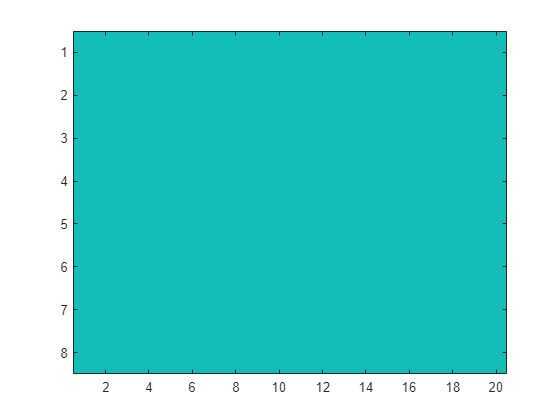

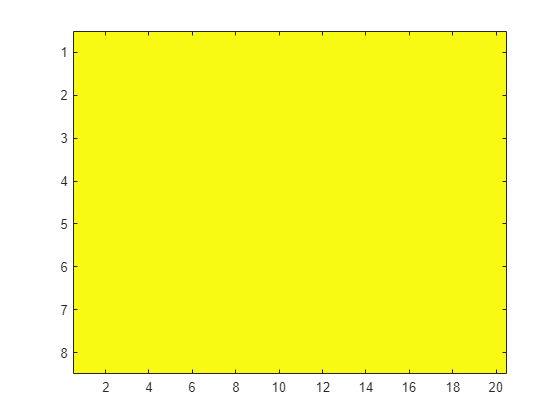

scale = 0.6400

count_x = 15

count_y = 5

level=3 count_x=15 count_y=5

level=3 0/75 (j=0, i=0)... 


pred=neg_64


level=3 1/75 (j=0, i=1)... 


pred=neg_64


level=3 2/75 (j=0, i=2)... 


pred=neg_64


level=3 3/75 (j=0, i=3)... 


pred=neg_64


level=3 4/75 (j=0, i=4)... 


pred=neg_64


level=3 5/75 (j=0, i=5)... 


pred=neg_64


level=3 6/75 (j=0, i=6)... 


pred=neg_64


level=3 7/75 (j=0, i=7)... 


pred=neg_64


level=3 8/75 (j=0, i=8)... 


pred=neg_64


level=3 9/75 (j=0, i=9)... 


pred=neg_64


level=3 10/75 (j=0, i=10)... 


pred=neg_64


level=3 11/75 (j=0, i=11)... 


pred=neg_64


level=3 12/75 (j=0, i=12)... 


pred=neg_64


level=3 13/75 (j=0, i=13)... 


pred=neg_64


level=3 14/75 (j=0, i=14)... 


pred=neg_64


level=3 15/75 (j=1, i=0)... 


pred=neg_64


level=3 16/75 (j=1, i=1)... 


pred=neg_64


level=3 17/75 (j=1, i=2)... 


pred=neg_64


level=3 18/75 (j=1, i=3)... 


pred=neg_64


level=3 19/75 (j=1, i=4)... 


pred=neg_64


level=3 20/75 (j=1, i=5)... 


pred=neg_64


level=3 21/75 (j=1, i=6)... 


pred=neg_64


level=3 22/75 (j=1, i=7)... 


pred=neg_64


level=3 23/75 (j=1, i=8)... 


pred=neg_64


level=3 24/75 (j=1, i=9)... 


pred=neg_64


level=3 25/75 (j=1, i=10)... 


pred=neg_64


level=3 26/75 (j=1, i=11)... 


pred=neg_64


level=3 27/75 (j=1, i=12)... 


pred=neg_64


level=3 28/75 (j=1, i=13)... 


pred=neg_64


level=3 29/75 (j=1, i=14)... 


pred=neg_64


level=3 30/75 (j=2, i=0)... 


pred=neg_64


level=3 31/75 (j=2, i=1)... 


pred=neg_64


level=3 32/75 (j=2, i=2)... 


pred=neg_64


level=3 33/75 (j=2, i=3)... 


pred=neg_64


level=3 34/75 (j=2, i=4)... 


pred=neg_64


level=3 35/75 (j=2, i=5)... 


pred=neg_64


level=3 36/75 (j=2, i=6)... 


pred=neg_64


level=3 37/75 (j=2, i=7)... 


pred=neg_64


level=3 38/75 (j=2, i=8)... 


pred=neg_64


level=3 39/75 (j=2, i=9)... 


pred=neg_64


level=3 40/75 (j=2, i=10)... 


pred=neg_64


level=3 41/75 (j=2, i=11)... 


pred=neg_64


level=3 42/75 (j=2, i=12)... 


pred=neg_64


level=3 43/75 (j=2, i=13)... 


pred=neg_64


level=3 44/75 (j=2, i=14)... 


pred=neg_64


level=3 45/75 (j=3, i=0)... 


pred=neg_64


level=3 46/75 (j=3, i=1)... 


pred=neg_64


level=3 47/75 (j=3, i=2)... 


pred=neg_64


level=3 48/75 (j=3, i=3)... 


pred=neg_64


level=3 49/75 (j=3, i=4)... 


pred=neg_64


level=3 50/75 (j=3, i=5)... 


pred=neg_64


level=3 51/75 (j=3, i=6)... 


pred=neg_64


level=3 52/75 (j=3, i=7)... 


pred=neg_64


level=3 53/75 (j=3, i=8)... 


pred=neg_64


level=3 54/75 (j=3, i=9)... 


pred=neg_64


level=3 55/75 (j=3, i=10)... 


pred=neg_64


level=3 56/75 (j=3, i=11)... 


pred=neg_64


level=3 57/75 (j=3, i=12)... 


pred=neg_64


level=3 58/75 (j=3, i=13)... 


pred=neg_64


level=3 59/75 (j=3, i=14)... 


pred=neg_64


level=3 60/75 (j=4, i=0)... 


pred=neg_64


level=3 61/75 (j=4, i=1)... 


pred=neg_64


level=3 62/75 (j=4, i=2)... 


pred=neg_64


level=3 63/75 (j=4, i=3)... 


pred=neg_64


level=3 64/75 (j=4, i=4)... 


pred=neg_64


level=3 65/75 (j=4, i=5)... 


pred=neg_64


level=3 66/75 (j=4, i=6)... 


pred=neg_64


level=3 67/75 (j=4, i=7)... 


pred=neg_64


level=3 68/75 (j=4, i=8)... 


pred=neg_64


level=3 69/75 (j=4, i=9)... 


pred=neg_64


level=3 70/75 (j=4, i=10)... 


pred=neg_64


level=3 71/75 (j=4, i=11)... 


pred=neg_64


level=3 72/75 (j=4, i=12)... 


pred=neg_64


level=3 73/75 (j=4, i=13)... 


pred=neg_64


level=3 74/75 (j=4, i=14)... 


pred=neg_64


best_score = 0

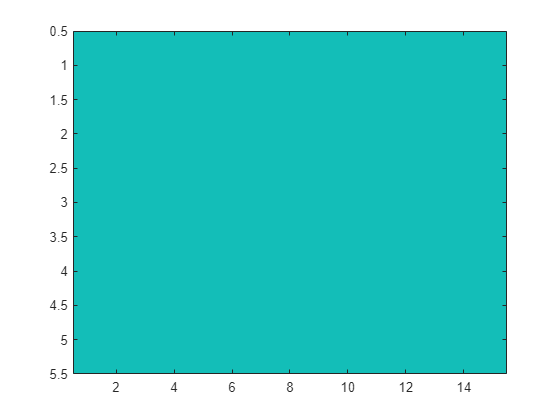

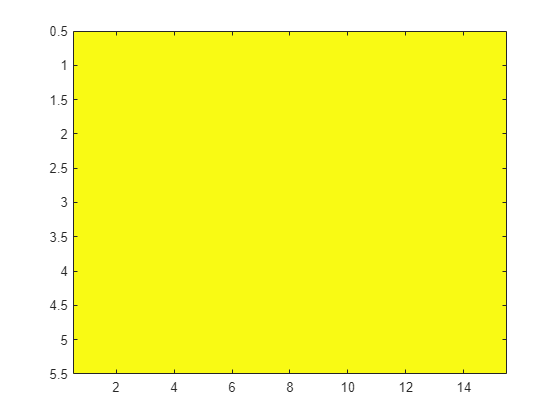

scale = 0.5120

count_x = 11

count_y = 3

level=4 count_x=11 count_y=3

level=4 0/33 (j=0, i=0)... 


pred=neg_64


level=4 1/33 (j=0, i=1)... 


pred=neg_64


level=4 2/33 (j=0, i=2)... 


pred=neg_64


level=4 3/33 (j=0, i=3)... 


pred=neg_64


level=4 4/33 (j=0, i=4)... 


pred=neg_64


level=4 5/33 (j=0, i=5)... 


pred=neg_64


level=4 6/33 (j=0, i=6)... 


pred=neg_64


level=4 7/33 (j=0, i=7)... 


pred=neg_64


level=4 8/33 (j=0, i=8)... 


pred=neg_64


level=4 9/33 (j=0, i=9)... 


pred=neg_64


level=4 10/33 (j=0, i=10)... 


pred=neg_64


level=4 11/33 (j=1, i=0)... 


pred=neg_64


level=4 12/33 (j=1, i=1)... 


pred=neg_64


level=4 13/33 (j=1, i=2)... 


pred=neg_64


level=4 14/33 (j=1, i=3)... 


pred=neg_64


level=4 15/33 (j=1, i=4)... 


pred=neg_64


level=4 16/33 (j=1, i=5)... 


pred=neg_64


level=4 17/33 (j=1, i=6)... 


pred=neg_64


level=4 18/33 (j=1, i=7)... 


pred=neg_64


level=4 19/33 (j=1, i=8)... 


pred=neg_64


level=4 20/33 (j=1, i=9)... 


pred=neg_64


level=4 21/33 (j=1, i=10)... 


pred=neg_64


level=4 22/33 (j=2, i=0)... 


pred=neg_64


level=4 23/33 (j=2, i=1)... 


pred=neg_64


level=4 24/33 (j=2, i=2)... 


pred=neg_64


level=4 25/33 (j=2, i=3)... 


pred=neg_64


level=4 26/33 (j=2, i=4)... 


pred=neg_64


level=4 27/33 (j=2, i=5)... 


pred=neg_64


level=4 28/33 (j=2, i=6)... 


pred=neg_64


level=4 29/33 (j=2, i=7)... 


pred=neg_64


level=4 30/33 (j=2, i=8)... 


pred=neg_64


level=4 31/33 (j=2, i=9)... 


pred=neg_64


level=4 32/33 (j=2, i=10)... 


pred=neg_64


best_score = 0

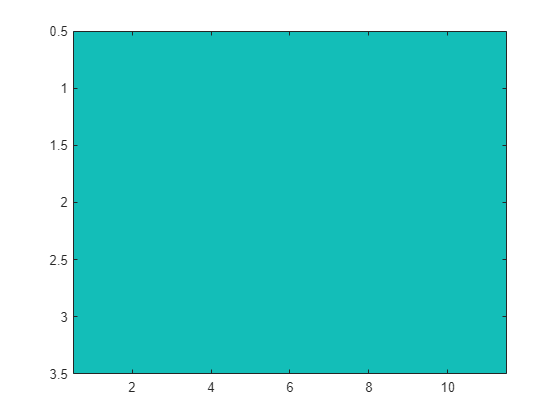

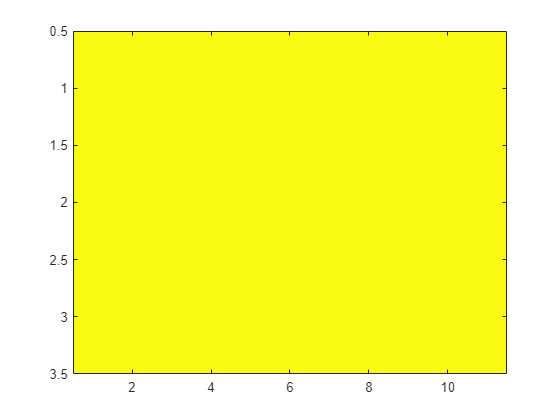

scale = 0.4096

count_x = 9

count_y = 1

level=5 count_x=9 count_y=1

level=5 0/9 (j=0, i=0)... 


pred=neg_64


level=5 1/9 (j=0, i=1)... 


pred=neg_64


level=5 2/9 (j=0, i=2)... 


pred=neg_64


level=5 3/9 (j=0, i=3)... 


pred=neg_64


level=5 4/9 (j=0, i=4)... 


pred=neg_64


level=5 5/9 (j=0, i=5)... 


pred=neg_64


level=5 6/9 (j=0, i=6)... 


pred=neg_64


level=5 7/9 (j=0, i=7)... 


pred=neg_64


level=5 8/9 (j=0, i=8)... 


pred=neg_64


best_score = 0

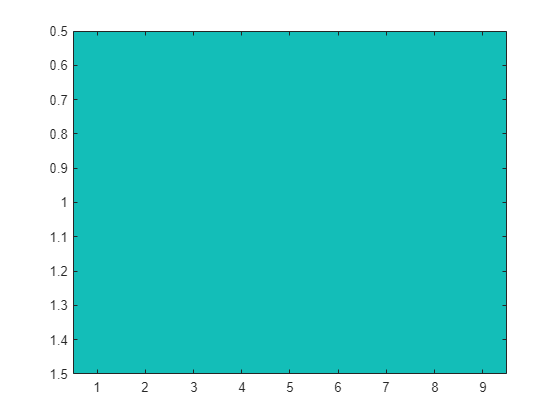

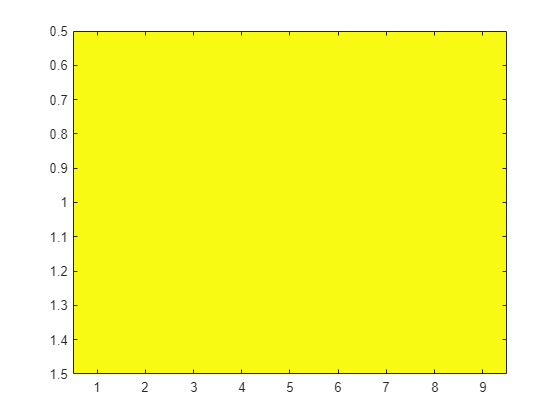



% Weryfikacja klasyfikatora
sx = 64;
sy = 128;
step = 24;

scale_step = 0.8;
levels = 5;

scale = 1.0;
thr = 0;

dets = [];
scores = [];
labels = {};


for k=1:levels

scale
cur_img = imresize(It, scale);

w = size(cur_img, 2);
h = size(cur_img, 1);

count_x = floor((w - sx) / step)
count_y = floor((h - sy) / step)

fprintf("level=%d count_x=%d count_y=%d", k, count_x, count_y)

out = zeros(count_y, count_x);

for j=0:count_y-1
    for i=0:count_x-1
        fprintf("level=%d %d/%d (j=%d, i=%d)... \n", k, j*count_x+i, count_y*count_x, j, i);
        x = 1+(i*step);
        y = 1+(j*step);
        sub_img = cur_img(y:y+sy, x:x+sx);
        [sub_hog, sub_vis] = extractHOGFeatures(sub_img);
        pred = model.predict(sub_hog);
        fprintf("pred=%s\n", pred);
        out(j+1, i+1) = strcmp(pred, 'pos');
    end
end

best_score = min(min(out))

figure;
imagesc(out)
figure;
mins = imregionalmin(out);
mins(out > thr) = 0;
imagesc(mins);
[rs, cs] = find(mins);

for i=1:size(rs)
    x = ((cs(i)-1) * step) / scale + 1;
    y = ((rs(i)-1) * step) / scale + 1;
    w = sx / scale;
    h = sy / scale;

    dets = [dets; [x,y,w,h] ];
    scores = [scores, out(rs(i), cs(i))];
    labels{size(dets, 1)} = num2str(out(rs(i), cs(i)), '%.1f');
end

scale = scale * scale_step;

end

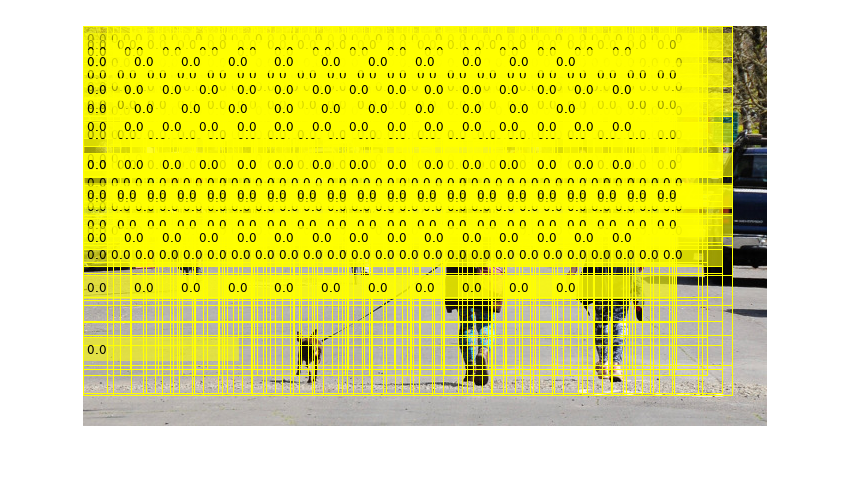

imshow(insertObjectAnnotation(It, 'rectangle', dets, labels));

### Filtracja detekcji i NMS

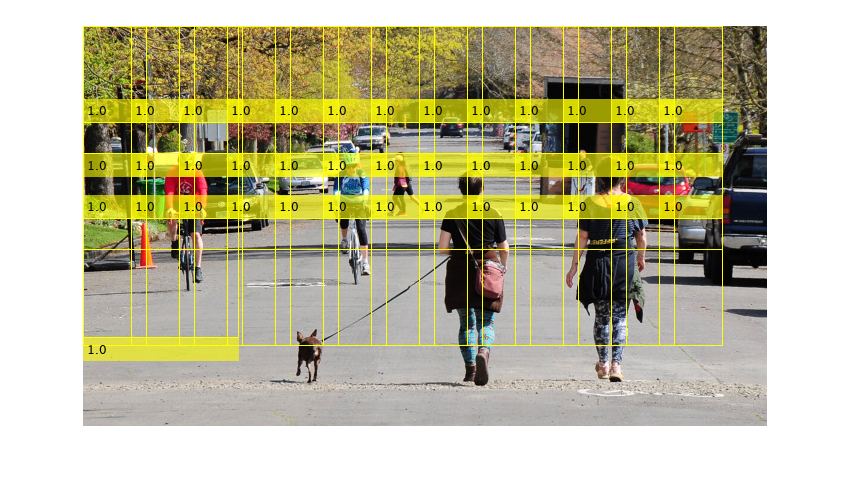

filtered_dets = [];
filtered_scores = [];
tmp_dets = dets;
tmp_scores = scores;
while 1
    [m, i] = min(tmp_scores);
    filtered_dets = [filtered_dets; tmp_dets(i,:)];
    filtered_scores = [filtered_scores, m];
    ratio = bboxOverlapRatio(tmp_dets(i, :), tmp_dets);
    tmp_dets = tmp_dets(ratio < 0.2, :);
    tmp_scores = tmp_scores(ratio < 0.2);
    if size(tmp_dets, 1) < 1
        break
    end
end
cnt = size(filtered_scores, 2);
filtered_lbls = cell(cnt, 1);
for i=1:cnt
    filtered_lbls{i} = num2str(filtered_scores(i), '%.1f');
end
imshow(insertObjectAnnotation(It, "rectangle", filtered_dets, filtered_lbls));

gt_rect=gTruth.LabelData.person{1,1};

Unable to resolve the name 'gTruth.LabelData.person'.

ann1 = insertObjectAnnotation(It, "rectangle", gt_rect, "person");
imshow(ann1);
score_thr = 30;
selected_dets = filtered_dets(filtered_scores < score_thr, :);
ratio = bboxOverlapRatio(gt_rect, selected_dets)
[best_overlaps, good_ids] = max(ratio, [], 2)
iou = 0.4;
best_ids = good_ids(best_overlaps > iou)
pos_neg = zeros(size(selected_dets, 1), 1);
pos_neg(best_ids) = 1;
tp_boxes = selected_dets(pos_neg==1, :);
fp_boxes = selected_dets(pos_neg==0, :);
ann2 = insertObjectAnnotation(ann1, "rectangle", fp_boxes, "", "Color", 'red');
ann2 = insertObjectAnnotation(ann2, "rectangle", tp_boxes, "", "Color", 'green');
imshow(ann2)

[P, R, sc] = calcpr(filtered_dets, filtered_scores, gt_rect, 0.4);
figure;
plot(sc, P);
hold on
plot(sc, R);
legend(["Precision", "Recall"]);
xlabel("Score");
ylabel("%");
figure;
plot(R, P, 'x-');
xlabel("Recall");
ylabel("Precision");
ap = trapz(R, P)

function [P, R, sc] = calcpr(dets, scores, gt_rect, iou)
    cnt = size(scores, 2) + 1;
    P = zeros(cnt, 1);
    R = zeros(cnt, 1);
    sorted_scores = sort(scores);
    
    sorted_scores = [0, sorted_scores];
    sc = sorted_scores;
    
    all_pos = size(gt_rect, 1);
    
    P(1) = 1;
    R(1) = 0;
    
    for ii=2:cnt
        score_thr = sorted_scores(ii);
        selected_dets = dets(scores <= score_thr, :);
        ratio = bboxOverlapRatio(gt_rect, selected_dets);
        [best_overlaps, good_ids] = max(ratio, [], 2);
        best_ids = good_ids(best_overlaps > iou);
        tp = size(best_ids, 1);
        fn = all_pos - tp;
        fp = size(selected_dets, 1) - tp;
        P(ii) = tp / (tp + fp);
        R(ii) = tp / (tp + fn);
    end
end